# Item 3

## Enunciado

Calcular sistema controlador que haga evolucionar al péndulo en el equilibrio estable. Objetivo de control: partiendo de una condición inicial nula en el desplazamiento y el ángulo en $\pi
$, hacer que el carro se desplace a 10 metros evitando las oscilaciones de la masa $m
$, considerando que es una grúa. Una vez que $\delta = 10$ modificar a $m
$ a un valor 10 veces mayor y volver al origen evitando oscilaciones.

- Considerar que sólo puede medirse el desplazamiento $\delta$ y el ángulo $\phi$

- Especificar el rango posible para el tiempo de muestreo para implementar el sistema en un microcontrolador.

- Determinar el efecto de la nolinealidad en la acción de control, descripta en la Fig. 4, y verificar cuál es el máximo valor admisible de ésa no linealidad.

## Resolución

Planteamos el modelo del péndulo linealizado a partir de las variables de estado.

clear all; close all; clc;
m1 = 0.1; m2 = 1; F = 0.1; l = 1.6; 
g = 9.8; M = 1.5;

A_m1 = [0       1           0           0;  
        0     -F/M       -m1*g/M        0;  
        0       0           0           1;  
        0    -F/(l*M)  -g*(m1+M)/(l*M)  0];


A_m2 = [0       1           0           0;  
        0     -F/M       -m2*g/M        0;  
        0       0           0           1;  
        0    -F/(l*M)  -g*(m2+M)/(l*M)  0];
   
B = [0; 1/M; 0; 1/(l*M)]; 

C = [1 0 0 0; 0 0 1 0]; %Salida delta y theta (medibles)

D = [0; 0];

A partir de las matrices del sistema, se analiza la controlabilidad.

 M_m1 = [B A_m1*B A_m1^2*B A_m1^3*B];
 M_m2 = [B A_m2*B A_m2^2*B A_m2^3*B];
 rank(M_m1)

ans = 4

 rank(M_m2)

ans = 4

Para el cálculo del controlador LQR, se debe tener en cuenta que existen dos sistemas con masa diferente, por lo cual se calculan dos controladores. Se procede a construir el sistema ampliado.

% Construcción del sistema ampliado
Aa_m1=[A_m1 zeros(4,1); -C(1,:) 0];
Aa_m2=[A_m2 zeros(4,1); -C(1,:) 0];
Ba=[B; 0];
Ca=[C(1,:) 0];


%Controlador 1
Q1 = diag([1 1000 1 1000 1]);
R1 = 1;
K1 = lqr(Aa_m1, Ba, Q1, R1)

K1 =     8.2967   33.8172   74.1907    8.8185   -1.0000


%Controlador 2
Q2 = diag([1 1000 1 1000 1]);
R2 = 1;

K2 = lqr(Aa_m2, Ba, Q2, R2)

K2 =     8.2995   33.8407   66.2382    8.4779   -1.0000


A partir de los valores obtenidos, se simula el sistema.

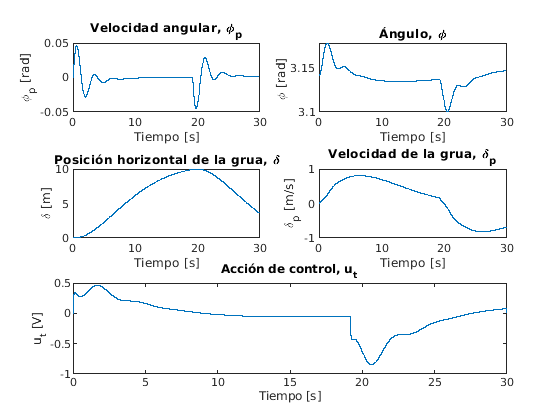

%Simulacion
tsim = 30;
h = 1e-4;
N = floor(tsim/h);
t = 0:h:(tsim);

% Prealocación de arrelgos
delta = zeros(1,N);
delta_p = zeros(1,N);
phi = zeros(1,N);
phi_p = zeros(1,N);
u = zeros(1,N+1);
psi = zeros(1,N);
% Valores iniciales y referencia
%ref=5*square(2*pi*t/tsim)+5;
ref = 10;
xop = [0; 0 ; pi ; 0];
x = [0; 0 ; pi ; 0];
phi(1) = pi; %cond inicial.
m  = m1;
%G = G1; 
flag = 0;
K_c  = K1;
A    = A_m1;
B    = B;
psita = 0;
delta_pp = 0;
phi_pp = 0;
int=0;
% Simulación
for i=1:N   
    
   psi_p=ref-C(1,:)*(x-xop);
   psi(i)=int+psi_p*h;
        
   u(i) = -K_c*[(x-xop);psi(i)];   
   
   % Simulacion de sistema no lineal.
   delta_pp = (1/(M+m))*(u(i) - m*l*phi_pp*cos(phi(i)) + m*l*phi_p(i)^2*sin(phi(i)) - F*delta_p(i));
   phi_pp = (1/l)*(g*sin(phi(i)) - delta_pp*cos(phi(i)));
   delta_p(i+1) = delta_p(i) + h*delta_pp;
   delta(i+1) = delta(i) + h*delta_p(i);
   phi_p(i+1) = phi_p(i) + h*phi_pp;
   phi(i+1)  = phi(i) + h*phi_p(i);
  
   if(delta(i) >= 9.99)
        if(flag == 0)
            ref  = 0;
            m  = m2;
            flag = 1;
            K_c  = K2;
        end
    end
   
   x = [delta(i+1); delta_p(i+1); phi(i+1); phi_p(i+1)];
   int=psi(i);
end

figure(1);

subplot(3,2,1); 
plot(t, phi_p);
title('Velocidad angular, \phi_p');
ylabel('\phi_p [rad]');
xlabel('Tiempo [s]');

subplot(3,2,2); 
plot(t, phi);
title('Ángulo, \phi');
ylabel('\phi [rad]');
xlabel('Tiempo [s]');

subplot(3,2,3);  
plot(t, delta);
title('Posición horizontal de la grua, \delta');
ylabel('\delta [m]');
xlabel('Tiempo [s]');

subplot(3,2,4);
plot(t, delta_p);
title('Velocidad de la grua, \delta_p');
ylabel('\delta_p [m/s]');
xlabel('Tiempo [s]');

subplot(3,1,3);
plot(t, u);
title('Acción de control, u_t');
ylabel('u_t [V]');
xlabel('Tiempo [s]');

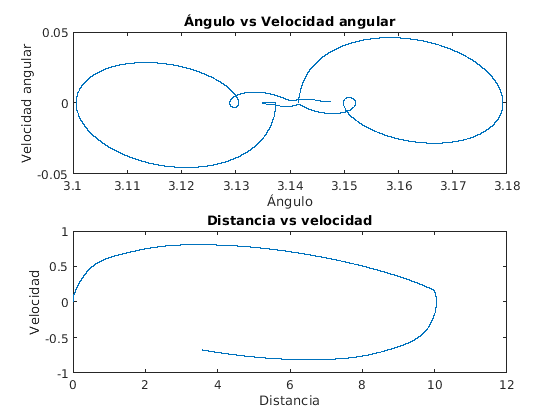


figure(2);
subplot(2,1,1)
plot(phi,phi_p);
title('Ángulo vs Velocidad angular');
xlabel('Ángulo');ylabel('Velocidad angular');
 
subplot(2,1,2)
plot(delta,delta_p);
title('Distancia vs velocidad');
xlabel('Distancia');ylabel('Velocidad');

A continuación se realiza la implementación de un observador para el caso de que solo se pueda medir el desplazamiento y el ángulo.

% Se deben realizar dos observadores diferentes.
% Primer observador
Ao1 = A_m1';
Bo1= C';
Qo1=1*diag([1 1/100 1 1]);    
Ro1=diag([1 1]); 
Ko1=lqr(Ao1,Bo1,Qo1,Ro1);

% Segundo observador
Ao2 = A_m2';
Bo2= C';
Qo2=1*diag([1 1/100 1 1]);    
Ro2=diag([1 1]);  
Ko2=lqr(Ao2,Bo2,Qo2,Ro2);

Simulando a partir de los observadores obtenidos.

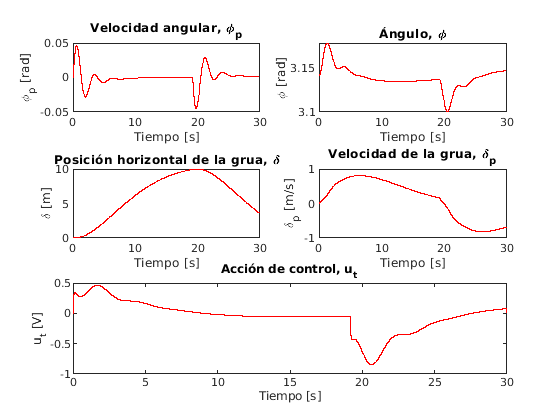

%Simulacion
tsim = 30;
h = 1e-4;
N = floor(tsim/h);
t = 0:h:(tsim);

% Prealocación de arrelgos
delta = zeros(1,N);
delta_p = zeros(1,N);
phi = zeros(1,N);
phi_p = zeros(1,N);
u = zeros(1,N+1);
psi = zeros(1,N);
delta_obs = zeros(1,N+1);
delta_p_obs = zeros(1,N+1);
phi_obs = zeros(1,N+1);
phi_p_obs = zeros(1,N+1);
% Valores iniciales y referencia
%ref=5*square(2*pi*t/tsim)+5;
ref = 10;
xop = [0; 0 ; pi ; 0];
x_hat = [0; 0 ; pi ; 0];
x = [0; 0 ; pi ; 0];
phi(1) = pi; %cond inicial.
phi_obs(1) = pi;
m  = m1;
%G = G1; 
flag = 0;
K_c  = K1;
A    = A_m1;
B    = B;
psita = 0;
delta_pp = 0;
phi_pp = 0;
int=0;
Ko_c = Ko1;
% Simulación
for i=1:N   
   y_sal_obs = C*x_hat;
   y_sal = C*x;
    
    
   psi_p=ref-C(1,:)*(x_hat-xop);
   psi(i)=int+psi_p*h;
        
   u(i) = -K_c*[(x_hat-xop);psi(i)];   
   
   % Simulacion de sistema no lineal.
   delta_pp = (1/(M+m))*(u(i) - m*l*phi_pp*cos(phi(i)) + m*l*phi_p(i)^2*sin(phi(i)) - F*delta_p(i));
   phi_pp = (1/l)*(g*sin(phi(i)) - delta_pp*cos(phi(i)));
   delta_p(i+1) = delta_p(i) + h*delta_pp;
   delta(i+1) = delta(i) + h*delta_p(i);
   phi_p(i+1) = phi_p(i) + h*phi_pp;
   phi(i+1)  = phi(i) + h*phi_p(i);
  
   if(delta(i) >= 9.99)
        if(flag == 0)
            ref  = 0;
            m  = m2;
            flag = 1;
            K_c  = K2;
            Ko_c = Ko2;
            A = A_m2;
        end
   end
   e=y_sal-y_sal_obs;
   
   x_hatp = A*(x_hat-xop)+B*u(i)+Ko_c'*e;
   x_hat = x_hat + x_hatp*h;
   
   delta_obs(i+1) = x_hat(1);
   delta_p_obs(i+1) = x_hat(2);
   phi_obs(i+1) = x_hat(3);
   phi_p_obs(i+1) = x_hat(4);
   
   x = [delta(i+1); delta_p(i+1); phi(i+1); phi_p(i+1)];
   int=psi(i);
end

figure(3);
subplot(3,2,1); 
plot(t, phi_p_obs, 'Color', 'r');
title('Velocidad angular, \phi_p');
ylabel('\phi_p [rad]');
xlabel('Tiempo [s]');

subplot(3,2,2); 
plot(t, phi_obs, 'Color', 'r');
title('Ángulo, \phi');
ylabel('\phi [rad]');
xlabel('Tiempo [s]');

subplot(3,2,3); 
plot(t, delta_obs, 'Color', 'r');
title('Posición horizontal de la grua, \delta');
ylabel('\delta [m]');
xlabel('Tiempo [s]');

subplot(3,2,4); 
plot(t, delta_p_obs, 'Color', 'r');
title('Velocidad de la grua, \delta_p');
ylabel('\delta_p [m/s]');
xlabel('Tiempo [s]');

subplot(3,1,3);
plot(t, u, 'Color', 'r');
title('Acción de control, u_t');
ylabel('u_t [V]');
xlabel('Tiempo [s]');

Si se agrega una zona muerta al actuador de 0.5, el sistema se continua comportando de manera similar.

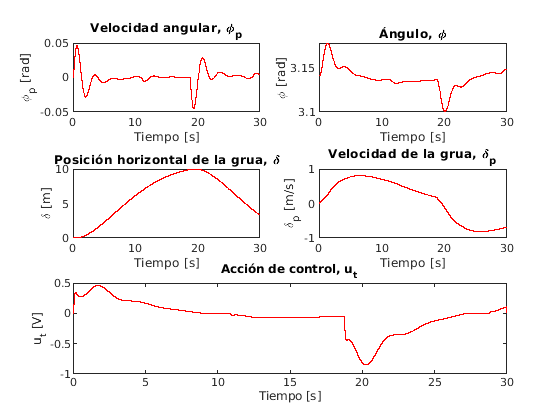

%Simulacion
tsim = 30;
h = 1e-4;
N = floor(tsim/h);
t = 0:h:(tsim);

% Prealocación de arrelgos
delta = zeros(1,N);
delta_p = zeros(1,N);
phi = zeros(1,N);
phi_p = zeros(1,N);
u = zeros(1,N+1);
psi = zeros(1,N);
delta_obs = zeros(1,N+1);
delta_p_obs = zeros(1,N+1);
phi_obs = zeros(1,N+1);
phi_p_obs = zeros(1,N+1);
% Valores iniciales y referencia
%ref=5*square(2*pi*t/tsim)+5;
ref = 10;
xop = [0; 0 ; pi ; 0];
x_hat = [0; 0 ; pi ; 0];
x = [0; 0 ; pi ; 0];
phi(1) = pi; %cond inicial.
phi_obs(1) = pi;
m  = m1;
%G = G1; 
flag = 0;
K_c  = K1;
A    = A_m1;
B    = B;
psita = 0;
delta_pp = 0;
phi_pp = 0;
int=0;
Ko_c = Ko1;
deadZone = 0.5;
% Simulación
for i=1:N   
   y_sal_obs = C*x_hat;
   y_sal = C*x;
    
   psi_p=ref-C(1,:)*(x_hat-xop);
   psi(i)=int+psi_p*h;
        
   u(i) = -K_c*[(x_hat-xop);psi(i)];  
   
   if(abs(u(i))<deadZone)
       u(i) = 0;
   else
       u(i) = sign(u(i))*(abs(u(i)) - deadZone);
   end
   
   % Simulacion de sistema no lineal.
   delta_pp = (1/(M+m))*(u(i) - m*l*phi_pp*cos(phi(i)) + m*l*phi_p(i)^2*sin(phi(i)) - F*delta_p(i));
   phi_pp = (1/l)*(g*sin(phi(i)) - delta_pp*cos(phi(i)));
   delta_p(i+1) = delta_p(i) + h*delta_pp;
   delta(i+1) = delta(i) + h*delta_p(i);
   phi_p(i+1) = phi_p(i) + h*phi_pp;
   phi(i+1)  = phi(i) + h*phi_p(i);
  
   if(delta(i) >= 9.99)
        if(flag == 0)
            ref  = 0;
            m  = m2;
            flag = 1;
            K_c  = K2;
            Ko_c = Ko2;
            A = A_m2;
        end
   end
   e=y_sal-y_sal_obs;
   
   x_hatp = A*(x_hat-xop)+B*u(i)+Ko_c'*e;
   x_hat = x_hat + x_hatp*h;
   
   delta_obs(i+1) = x_hat(1);
   delta_p_obs(i+1) = x_hat(2);
   phi_obs(i+1) = x_hat(3);
   phi_p_obs(i+1) = x_hat(4);
   
   x = [delta(i+1); delta_p(i+1); phi(i+1); phi_p(i+1)];
   int=psi(i);
end

figure(4);
subplot(3,2,1); 
plot(t, phi_p_obs, 'Color', 'r');
title('Velocidad angular, \phi_p');
ylabel('\phi_p [rad]');
xlabel('Tiempo [s]');

subplot(3,2,2); 
plot(t, phi_obs, 'Color', 'r');
title('Ángulo, \phi');
ylabel('\phi [rad]');
xlabel('Tiempo [s]');

subplot(3,2,3); 
plot(t, delta_obs, 'Color', 'r');
title('Posición horizontal de la grua, \delta');
ylabel('\delta [m]');
xlabel('Tiempo [s]');

subplot(3,2,4); 
plot(t, delta_p_obs, 'Color', 'r');
title('Velocidad de la grua, \delta_p');
ylabel('\delta_p [m/s]');
xlabel('Tiempo [s]');

subplot(3,1,3);
plot(t, u, 'Color', 'r');
title('Acción de control, u_t');
ylabel('u_t [V]');
xlabel('Tiempo [s]');